## Arduino LED Control Script

Clear workspace and command window

clear all %#ok<CLALL> 
clc

List serial ports

display(serialportlist)

  1×3 string array

    "COM6"    "COM8"    "COM18"



Create Serial object on Arduino COM port with matching baudrate and open it

s = serialport('COM18', 9600);

Declare variables

NUM_PIXELS = 8;
ADDR_PER_PIXEL = 4;
STRLEN = 24+2;
PACKET_LENGTH = 1024;
num = 0;

Helper function declaration

led_write = @(n, val) write(s, sprintf("%u=%u", n, val), 'string');
led_read = @() strtrim(read(s, STRLEN, 'string'));

led_write(0, 255);
led_read()

ans = "Addr 0: Color = 0x000000"

Set first LED to blue

led_write(3, 255);
led_read()

ans = "Addr 0: Color = 0x0000FE"

Clear first LED blue color

led_write(3, 0);
led_read()

ans = "Addr 0: Color = 0x000000"

Loop for writing all LEDs

for i = 0:ADDR_PER_PIXEL:(ADDR_PER_PIXEL*NUM_PIXELS)-1
    led_write(i+1, 0);
    led_read();
end

Open ECG dataset

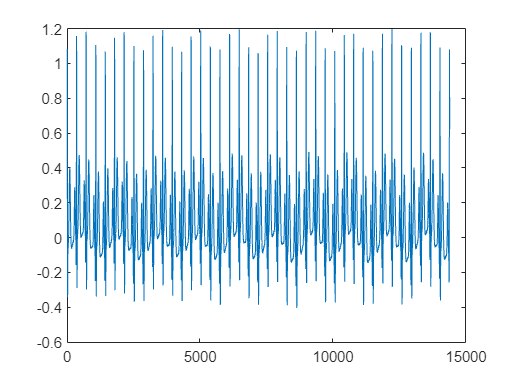

load('./Previous/MatFiles/ex_ecgdata360Hz.mat');
ecg = ecgdata360Hz_hrmean60;
plot(ecg)

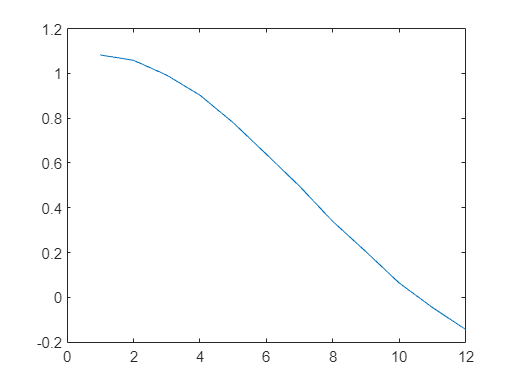


packet = ecg(1:12);
plot(packet)

Scale ECG data

[minValue, maxValue] = bounds(ecg);
% Why would you do this?
%ecg = (ecg-minValue)*1920/(maxValue-minValue);
%plot(ecg)

Find peaks of ECG data by saving locations where peak prominances are greater than 0.60 of the highest prominance peak

[peaks, locations, widths, prominances] = findpeaks(ecg);
threshold = max(prominances) * .60

threshold = single
0.9491

ecg_peak_locations = locations(prominances > threshold);

Calculate heart rate by taking the mean of the gaps between ecg peaks and converting it into BPM

peak_gap = zeros;
for i = 2:length(ecg_peak_locations)
    peak_gap(i-1) = ecg_peak_locations(i) - ecg_peak_locations(i-1);
end

BPM = round(360 / mean(peak_gap) * 60, 0)

BPM = 60

Disconnect and clear serialport connection

clear s